clear; clc; close all;

syms x1 x2 x3 x4  u
% parametros del sistema
ma=0.6; % masa brazo [kg]
mp=0.2; % masa pendulo [kg]
la=1.1600e-1; % largo del brazo [m]
lp=3.0001e-1; % largo del pendulo [m]
j0=(ma*la^2)/3; %inercia brazo [kg m^2]
g=9.8;  % gravedad [m/s^-2]
j1=(mp*lp^2)/3; % inercia pendulo [kg m^2]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Ts=0.01;% tiempo de muestreo


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x1: angulo del brazo (\phi)
% x2: velocidad angular del brazo (\dot\phi)
% x3: angulo del pendulo (\theta)
% x4: velocidad angular del pendulo (\dot\theta)
% u: torque del motor 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sistema no lineal pendulo
a1=((ma+mp)/3)*la^2;  %alfa
a2=(mp*lp^2)/3;       %beta
a3=(mp*la*lp)/2;      %lambda
a4=(mp*g*lp)/2;       %delta
den=((a1*a2)-a3^2)+((a2^2+a3^2)*sin(x3)^2);
% campo vectorial
f1=x2;
f2=((a2*a3*(sin(x3)^2-1)*sin(x3)*x2^2)-...
    (2*a2^2*cos(x3)*sin(x3)*x2*x4)+(a2*a3*sin(x3)*x4^2)-...
    (a3*a4*cos(x3)*sin(x3))+(a2*u))/den;
f3=x4;
f4=((a2*(a1+a2*sin(x3)^2)*cos(x3)*sin(x3)*x2^2)+...
    (2*a2*a3*(1-sin(x3)^2)*sin(x3)*x2*x4)-...
    (a3^2*cos(x3)*sin(x3)*x4^2)+(a4*(a1+a2*sin(x3)^2)*sin(x3))-...
    (a3*cos(x3)*u))/den;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

f = [f1; f2; f3; f4];


## 2. LINEALIZACIÓN DEL SISTEMA

A_sym = jacobian(f, [x1; x2; x3; x4]);
B_sym = jacobian(f, u);

ref=0;
x1ss=0;
x2ss=0;
x3ss= ref;
x4ss=0;
uss=(3*g*la*mp*sin(2*ref))/8;

A = double(subs(A_sym, [x1, x2, x3, x4, u], [x1ss x2ss x3ss x4ss uss]));
B = double(subs(B_sym, [x1, x2, x3, x4, u], [x1ss x2ss x3ss x4ss uss]));
C = [1 0 0 0]; 
D = 0;

%% 3. DISEÑO DEL CONTROLADOR POR ASIGNACIÓN DE POLOS (POLE PLACEMENT)
% Construcción de las matrices aumentadas (6x6) con doble integrador
Aa = [A,  zeros(4, 1);
      -C, 0];
Ba = [B;
      0];

zeta = 1;tsdes = 3;
wn = 4.6 / (zeta * tsdes);
polos_dominantes = roots([1, 2*zeta*wn, wn^2]);
polos_secundarios = [-0.3, -6, -5];
polos_deseados = [polos_dominantes', polos_secundarios];

% Polos más lejanos 
sistReferencia=tf([0 0 1],[1 2*zeta*wn wn^2])


sistReferencia =
 
            1
  ---------------------
  s^2 + 3.067 s + 2.351
 
Continuous-time transfer function.
Model Properties


polosz=[pole(sistReferencia)' -3 -3 -4];

%polosz=[pole(sistReferencia)' -1 -6 -5];
%polosz=[pole(sistReferencia)' -0.3 -6 -5]
K = acker(Aa, Ba, polosz);
disp(K);

   -0.0060   -0.0052   -0.4922   -0.0443    0.0027




%%% Se usa Ka como en tu código original para la ganancia aumentada
K1 = acker(Aa, Ba, polos_deseados);
disp(K1);

   -0.0034   -0.0044   -0.4993   -0.0465    0.0007




%% 4. SIMULACIÓN DEL CONTROLADOR
Tsim = 60;
Ns = round(Tsim/Ts);

ref = deg2rad(30); % referencia en radianes

x_0 = [0; 0; 0; 0];  % estado inicial
u_ctrl = 0;                  % señal de control inicial
int_err = 0;                 % error integrado

x = zeros(Ns, 4);            % historial de estados
usim = zeros(Ns, 1);         % historial de control
ref_hist = zeros(Ns, 1);     % historial de referencias
e_hist = zeros(Ns, 1);       % historial de errores

x_actual = x_0;
time = (0:Ns-1) * Ts;

for i = 2:Ns
    % Referencia escalonada
        if i*Ts >5
        ref = 60*pi/180;
    end
    if i*Ts >10
        ref = 90*pi/180;
    end
    if i*Ts >15
        ref = 120*pi/180;
    end
    if i*Ts >20
        ref = 160*pi/180;
    end
    if i*Ts >25
        ref = 210*pi/180;
    end
    if i*Ts >30
        ref = 250*pi/180;
    end
    if i*Ts >35
        ref = 290*pi/180;
    end
    if i*Ts >40
        ref = 340*pi/180;
    end
    if i*Ts >45
        ref = 380*pi/180;
    end
    if i*Ts >50
        ref = 410*pi/180;
    end
    if i*Ts >55
        ref = 440*pi/180;
    end

    % Simulación del sistema no lineal (debes tener esta función implementada)
    [~, xd] = ode45(@(t, x_state) complex_rot_pend(t, x_state, [], u_ctrl), [0 Ts], x_actual);
    xmed = xd(end, :)';

    % Cálculo del error entre referencia y salida (ángulo del brazo x1)
    e = ref - xmed(1);
    int_err = int_err + e * Ts;

    % Vector aumentado
    x_control = [xmed; int_err];

    % Control
    u_ctrl = -K * x_control;

    % Guardar resultados
    x_actual = xmed;
    x(i, :) = xmed';
    usim(i) = u_ctrl;
    ref_hist(i) = ref;
    e_hist(i) = e;
end

disp('Simulación finalizada.');

Simulación finalizada.


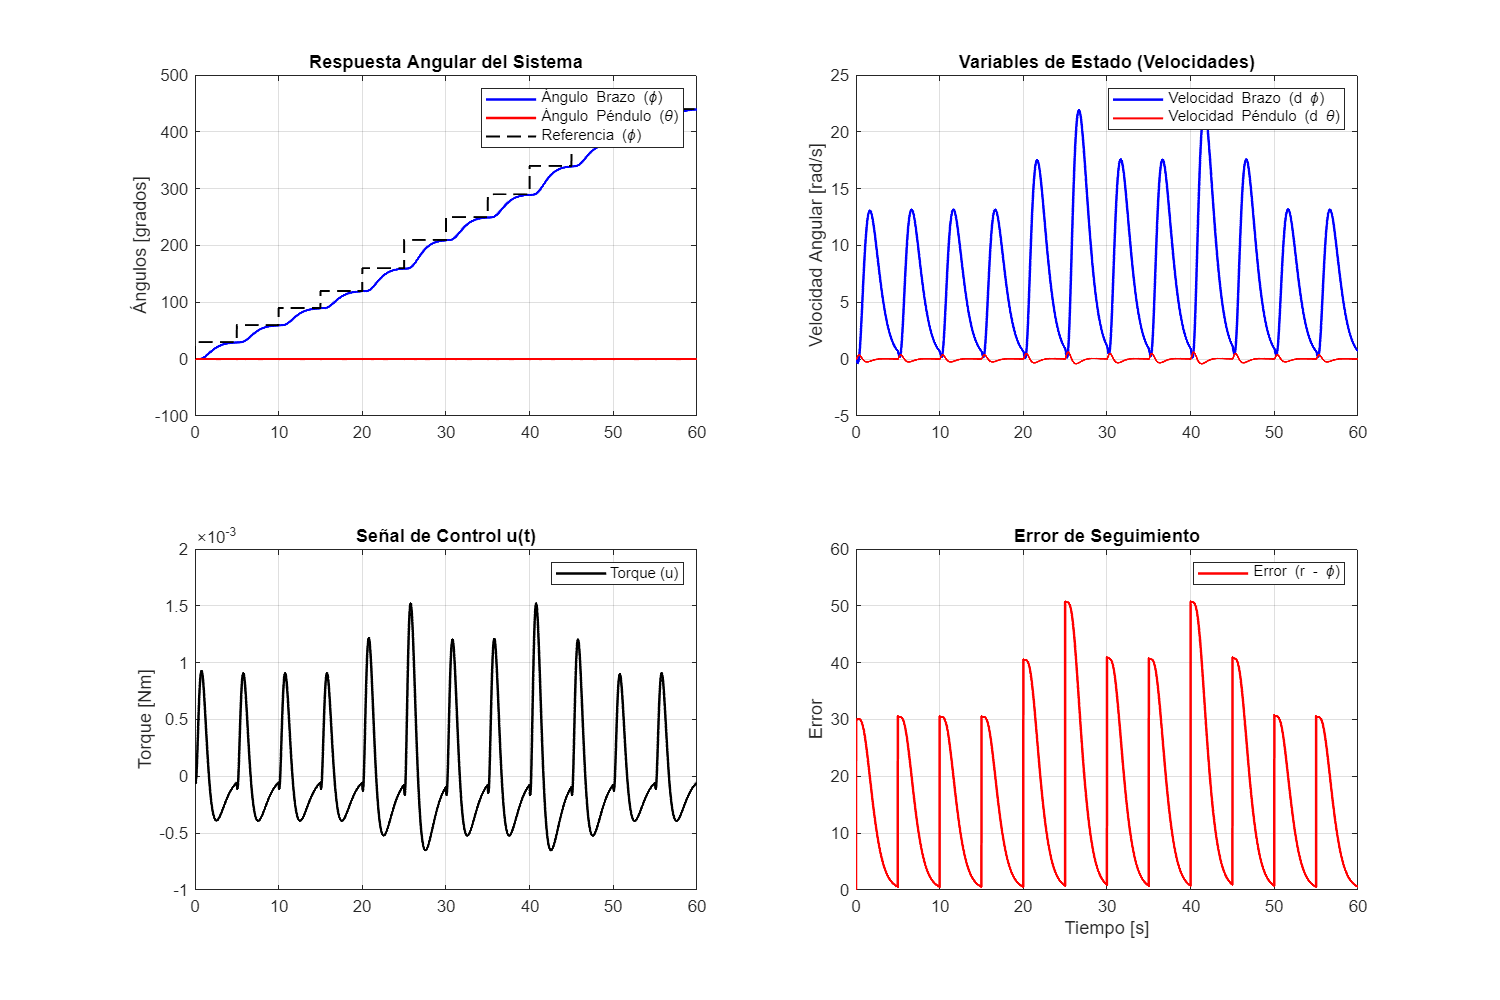


%% 5. GRÁFICAS DE RESULTADOS
td = (0:Ns-1) * Ts;


%% Gráficas Corregidas
figure('Position', [100, 100, 1200, 800]);

subplot(2,2,1)
plot(td, rad2deg(x(:,1)), 'blue', 'LineWidth', 1.5) % x1: Ángulo del brazo
hold on
plot(td, rad2deg(x(:,3)), 'red', 'LineWidth', 1.5);   % x3: Ángulo del péndulo
plot(td, rad2deg(ref_hist), 'black--', 'LineWidth', 1.2);
ylabel('Ángulos [grados]')
legend('Ángulo Brazo (\phi)', 'Ángulo Péndulo (\theta)', 'Referencia (\phi)');
title('Respuesta Angular del Sistema')
grid on

subplot(2,2,2)
plot(td, rad2deg(x(:,2)), 'blue', 'LineWidth', 1.5); % x2: Vel. angular brazo
hold on
plot(td, rad2deg(x(:,4)), 'red', 'LineWidth', 1.2);   % x4: Vel. angular péndulo
ylabel('Velocidad Angular [rad/s]')
legend('Velocidad Brazo (d \phi)', 'Velocidad Péndulo (d \theta)');
title('Variables de Estado (Velocidades)')
grid on

subplot(2,2,3)
plot(td, usim, 'k', 'LineWidth', 1.5)
ylabel('Torque [Nm]')
legend('Torque (u)');
title('Señal de Control u(t)')
grid on

subplot(2,2,4)
plot(td, rad2deg(e_hist), 'r', 'LineWidth', 1.5)
xlabel('Tiempo [s]')
ylabel('Error')
legend('Error (r - \phi)');
title('Error de Seguimiento')
grid on



set(gcf, 'Color', 'w');


% Cálculo de ITAE y energía
ITAE = trapz(time, time .* abs(e_hist')) * Ts; % Integral del tiempo por error absoluto
Energy = trapz(time, usim.^2) * Ts; % Energía de la señal de control
fprintf('ITAE: %.4f\n', ITAE);

ITAE: 5.0722


fprintf('Energía: %.4f\n', Energy);

Energía: 0.0000


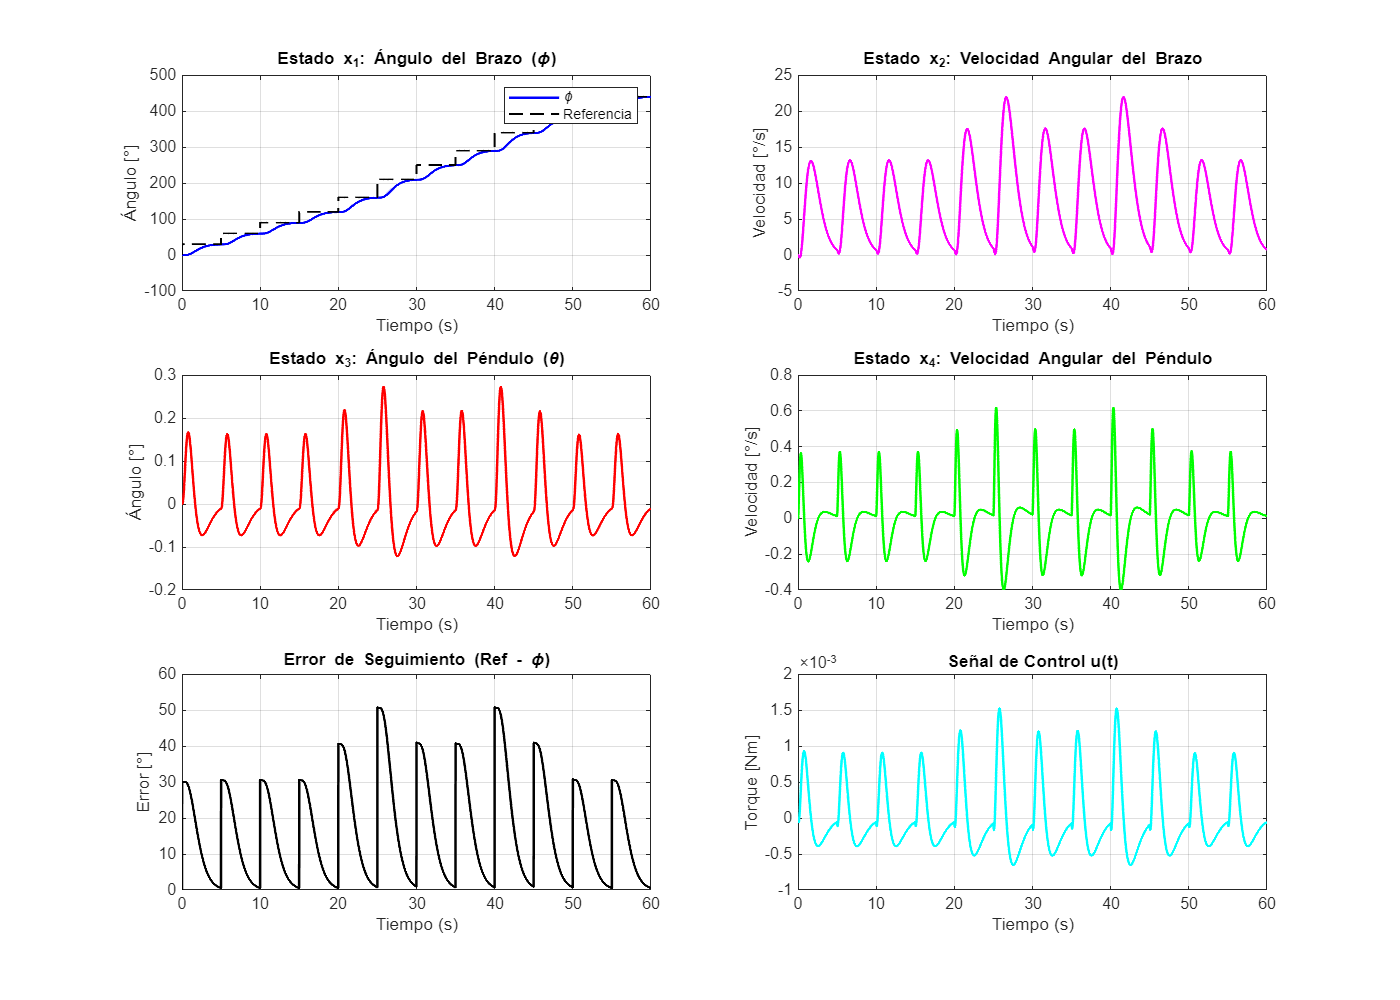



figure('Position', [100, 100, 1400, 1000]);

% Estados
subplot(3,2,1);
plot(td, rad2deg(x(:,1)), 'b', 'LineWidth', 1.5); hold on;
plot(td, rad2deg(ref_hist), 'k--', 'LineWidth', 1.2);
title('Estado x_1: Ángulo del Brazo (\phi)');
xlabel('Tiempo (s)'); ylabel('Ángulo [°]');
legend('\phi', 'Referencia'); grid on;

subplot(3,2,2);
plot(td, rad2deg(x(:,2)), 'm', 'LineWidth', 1.5);
title('Estado x_2: Velocidad Angular del Brazo');
xlabel('Tiempo (s)'); ylabel('Velocidad [°/s]');
grid on;

subplot(3,2,3);
plot(td, rad2deg(x(:,3)), 'r', 'LineWidth', 1.5);
title('Estado x_3: Ángulo del Péndulo (\theta)');
xlabel('Tiempo (s)'); ylabel('Ángulo [°]');
grid on;

subplot(3,2,4);
plot(td, rad2deg(x(:,4)), 'g', 'LineWidth', 1.5);
title('Estado x_4: Velocidad Angular del Péndulo');
xlabel('Tiempo (s)'); ylabel('Velocidad [°/s]');
grid on;

% Error de seguimiento
subplot(3,2,5);
plot(td, rad2deg(e_hist), 'k', 'LineWidth', 1.5);
title('Error de Seguimiento (Ref - \phi)');
xlabel('Tiempo (s)'); ylabel('Error [°]');
grid on;

% Señal de control
subplot(3,2,6);
plot(td, usim, 'c', 'LineWidth', 1.5);
title('Señal de Control u(t)');
xlabel('Tiempo (s)'); ylabel('Torque [Nm]');
grid on;